% 物理量
c0 = 3*1e8;
f0 = 20e9;% 工作频点（Hz）
lambda0 = c0/(f0);
beta0  = 2*pi/lambda0;
lambda1 = lambda0 * 2/3

lambda1 = 0.0100

k0 = 2*pi/lambda0;


% 阵列量
Nx  = 6.5;% x方向单元个数
Ny = 6.5;% y方向单元个数
dx = 1*lambda0;% x方向单元间距
dy = 1*lambda0;% y方向单元间距
Lx = Nx * dx;
Ly = Ny * dy;

% 建立坐标系
% 创建网格
resolution = 1;
Theta = linspace(-90, 90, 180 * resolution + 1);Phi = linspace(0, 45, 2);
[theta, phi] = meshgrid(Theta, Phi);

% 生成周期点坐标。
xPosmm = -dx*(Nx-1)/2:dx:dx*(Nx-1)/2;
yPosmm = -dy*(Ny-1)/2:dy:dy*(Ny-1)/2;
[xpos,ypos] = meshgrid(xPosmm,yPosmm);
periodic_points = [xpos(:),ypos(:)];

% replicate = 1;
% points = all_points{1};
% lambda0 = lambda0;
% hyperuniform_points_normed = [];
% hyperuniform_points_base = points .* [Lx, Ly] - [Lx/2, Ly/2];
% for nx = 0:(replicate - 1)
%     for ny = 0:replicate - 1
%         hyperuniform_points_normed = [hyperuniform_points_normed; hyperuniform_points_base + [Lx * nx, Ly * ny]];
%     end
% end

% 选择点
points = periodic_points;
N = size(points, 1);
% rad2deg(asin(lambda0/Lx * sqrt(K)))% theta exc
% rad2deg(asin(lambda0/Lx * sqrt(K)-sqrt(3)/2))
% % rad2deg(asin(lambda0/Lx * sqrt(K1)))
% (Lx/lambda1*(1+sqrt(3)/2) )^2 % 扫描不出现随机区的K
% sqrt(K) %法向不出现随机区的L
% sqrt(K)/(sqrt(3)/2+1) %扫描不出现随机区的L
% thetaScanDeg = -60
% % nx = -round(sqrt(K1)):1:round(sqrt(K1))
% theta0 = rad2deg(asin(lambda0/Lx * nx + sind(thetaScanDeg)));
% theta0 = theta0(imag(theta0)==0)

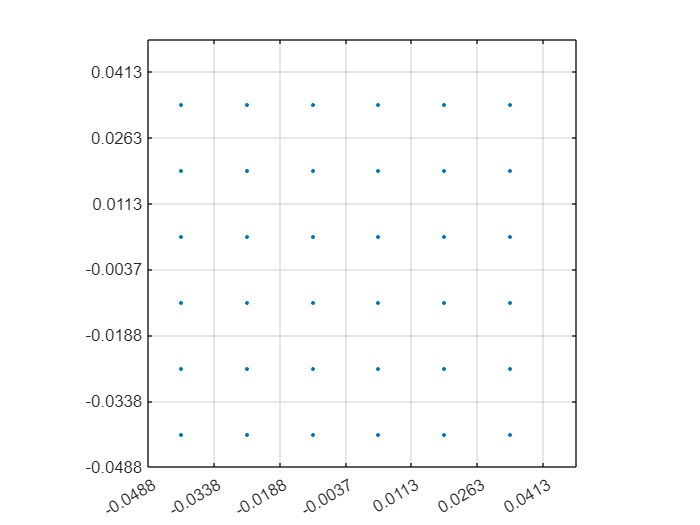

% 绘制点分布
figure;
scatter(points(:, 1), points(:, 2), 50, '.');
axis equal;  
xlim([-Lx/2, Lx/2]);
ylim([-Lx/2, Ly/2]);

% 获取当前 X 轴和 Y 轴的数据范围
xlims = xlim; % 获取 X 轴限制
ylims = ylim; % 获取 Y 轴限制

% 定义你想要的网格数量（例如，每个方向上 20 条线）
numGridLinesX = Nx;
numGridLinesY = Ny;

% 计算间隔
intervalX = diff(xlims) / numGridLinesX;
intervalY = diff(ylims) / numGridLinesY;

% 设置 X 轴和 Y 轴的刻度位置
xticks(xlims(1):intervalX:xlims(2));
yticks(ylims(1):intervalY:ylims(2));

% 确保网格可见
grid on;
box on;

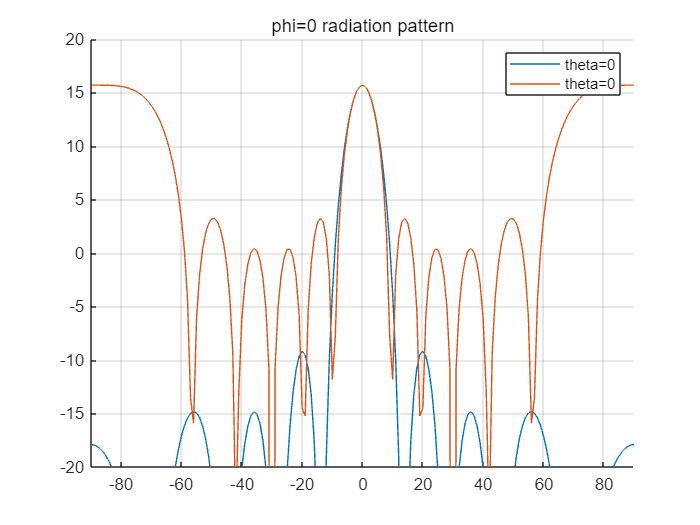

% 反射阵
phi_ = 0;
phiScanDeg = 0;
thetaScanDeg_array = [0,-20,-40,-60];
% 生成uv
u = sind(theta).*cosd(phi);
v = sind(theta).*sind(phi);

% 基础反射阵列参数
rf = [0,0, sqrt(2) * Ny * dy];
qe = 1/2;
qf = 8;
phase0 = 0;

figure ;
hold on;

a = 0;% 选择多个角度
for thetaScanDeg = 0
% 扫描角
    F = zeros(size(theta, 1),size(theta, 2));
    u0 = [sind(thetaScanDeg)*cosd(phiScanDeg), sind(thetaScanDeg)*sind(phiScanDeg), 0];
    for n = 1:N
        rn = [points(n,:),0];
%         c = rn - rf;
%         if norm(rn) == 0
%             theta_fn = 0;
%         else 
%             theta_fn = acos(dot(-rn,c) / (norm(rn)*norm(c))) - pi/2;
%         end
% %         theta_fn = 0;
        An = 1 ;
%         Rn = norm(rn - rf);
%         phase_n = k0 * (Rn - dot(rn, u0)) + phase0; 
%         I = cos(theta_fn) .^ qf * exp(-1j * k0 * Rn) * abs(cos(theta_fn) .^ qe) * exp(1j * phase_n);
%         F = F + An * I;
        phase_n = k0 * (-dot(rn, u0));
        F = F + An .* exp(1j * k0 * (rn(1) * u + rn(2) * v) + 1j * phase_n);
    end
    
%     PSLL = calculatePSLL2D(F, Lx, lambda0);
    S = abs(F);
    P_rad = sqrt(N-1);
    % 方向图绘制, 辐射功率方向图
    intensity_pattern = S/P_rad; 
    normalized_intensity_pattern = intensity_pattern; % 归一化处理
    dB_intensity_pattern = 20 * log10(normalized_intensity_pattern);
    plot(Theta, dB_intensity_pattern(2, :), 'DisplayName', "theta=" + num2str(thetaScanDeg));
    plot(Theta, dB_intensity_pattern(1, :), 'DisplayName', "theta=" + num2str(thetaScanDeg));
    title("phi=" + num2str(phi_) +" radiation pattern");
    xlim([-90, 90]);
    ylim([-20, 20]);
end
hold off;
legend;
grid on;